% Define the given set of vectors 
A = [1 0 0; 1 1 1; 0 0 1]'; 
% Initialize an empty matrix to store orthogonal vectors 
Q = zeros(size(A)); 
% Perform Gram-Schmidt Orthogonalization 
for j = 1:size(A, 2) 
    v = A(:, j); 
    for i = 1:j-1 
        q = Q(:, i); 
        v = v - (v' * q) * q; 
    end 
    Q(:, j) = v / norm(v); 
end 
disp(Q) 

    1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071



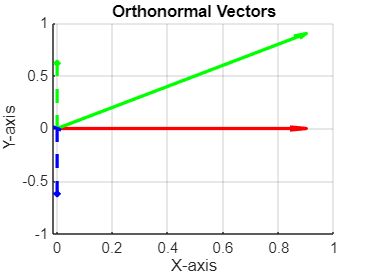

% Plot the orthonormal vectors 
figure; 
hold on; 
quiver3(0, 0, 0, Q(1,1), Q(2,1), Q(3,1), 'r--', 'LineWidth', 2); 
quiver3(0, 0, 0, Q(1,2), Q(2,2), Q(3,2), 'g--', 'LineWidth', 2); 
quiver3(0, 0, 0, Q(1,3), Q(2,3), Q(3,3), 'b--', 'LineWidth', 2); 
 
quiver3(0, 0, 0, A(1,1), A(2,1), A(3,1), 'r', 'LineWidth', 2); 
quiver3(0, 0, 0, A(1,2), A(2,2), A(3,2), 'g', 'LineWidth', 2); 
quiver3(0, 0, 0, A(1,3), A(2,3), A(3,3), 'b', 'LineWidth', 2); 
xlabel('X-axis'); 
ylabel('Y-axis'); 
title('Orthonormal Vectors'); 
grid on;